# ***HW2_Software_Assigment***

## ***Dr. Behzad Ahi***

## ***MohammadParsa Dini***

# ***400101204***

***Problem 7:***

In this section, we have implemented a function that takes the transfer function's numerator and denominator in polynomial form

and whether we wish to reform it into Controllable Canonical / Observable Canonical, it will return the proper matrices. 

% function [A, B, C] = canonical_form_(sys, form)
%     [numerator, denominator] = tfdata(sys, 'v');
%     an = denominator;
%     bn = numerator;
%     n = length(an) - 1;
%  % Controllable Canonical Form
%     if form == 'C'
%         A = zeros(n);
%         for i = 1:n-1
%             A(i, i+1) = 1;
%         end
%         A(n, :) = -an(2:end);
%         B = zeros(n, 1);
%         B(n) = 1;
%         C = bn;
%  % Observable Canonical Form
%     elseif form == 'O' 
%         A = zeros(n);
%         for i = 1:n-1
%             A(i+1, i) = 1;
%         end
%         A(:, 1) = -flip(an(2:end));
%         B = transpose(flip(bn));
%         C = [1, zeros(1, n-1)];
%     else
%         error('invalid input, the second argument must be either C or O');
%     end
% end

So in order to check our function, we will let $H(s) = \frac{s^2 + 4}{s(s+1)(s+2)} = \frac{s^2+4}{s^3 +3s^2+ 2s}$and hence 

$b_2=1, b_1=0, b_0= 4
$ and $a_2=3, a_1=2,a_0 = 0$ 

Here we test our function's output:

s = tf('s');
h_sys = (s^2+4)/(s*(s+1)*(s+2));
% Controllable Canonical Form 
[A1,B1,C1] = canonical_form_(h_sys,"C");
A1

A1 =      0     1     0
     0     0     1
     0    -2    -3


B1

B1 =      0
     0
     1


C1

C1 =      4     0     1


% Observable Canonical Form
[A2,B2,C2] = canonical_form_(h_sys,"O");
A2

A2 =      0     0     0
    -2     0     0
    -3     1     0


B2 =      1
     0
     4


B2
C2

C2 =      1     0     0


And as we see we got valid results !

***Problem 7:***

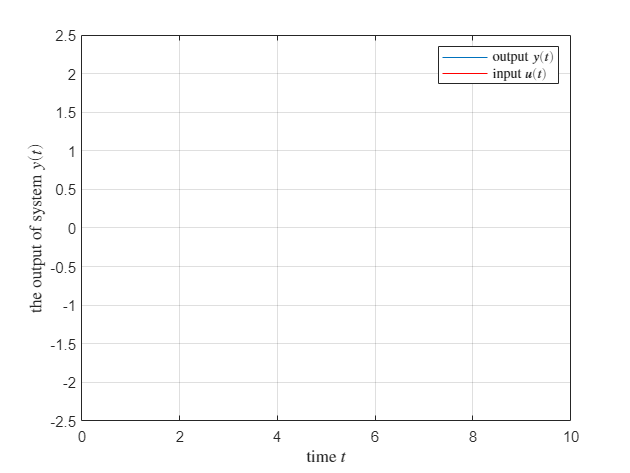

clear;
close all;
% the matrices A, B, C
A = [-1,1,0,0,0 ;
     0,-1,0,0,0;
     0,0,-2,0,0;
     0,0,0,-1,1;
     0,0,0,-1,-1];
B = transpose([0,1,1,0,1]);
C = [1,1,1,1,0];
% defining the time step
dt = 0.01;
t = 0:dt:10;
% defining the input
u = (t>=2 & t<=4);
u = u - (t>=6 & t<=8);
% defining the initial condition
x0 = [0,0,0,0,0];
% defining the transfer function 
sys = ss(A,B,C,0);
% computing the output with lsim
[y, tOut, x] = lsim(sys, u, t, x0);
% plotting the result
fig1 = figure();
plot(tOut,y);
hold on
plot(tOut,u,'r');
legend("output $y(t)$","input $u(t)$",'Interpreter', 'latex');
ylabel("the output of system $y(t)$",'Interpreter', 'latex');
xlabel("time $t$",'Interpreter', 'latex');
grid on

And eventually the states of the system $x_1(t)$ , $x_2(t)$ , $x_3(t)$ , $x_4(t)$and $x_5(t)$are depicted down here:

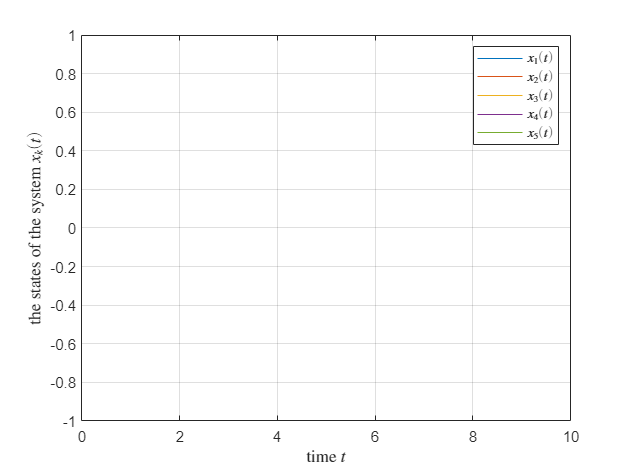

warning off;
fig2 = figure();
plot(t,x)
legend("$x_1(t)$","$x_2(t)$","$x_3(t)$","$x_4(t)$","$x_5(t)$",'Interpreter', 'latex');
ylabel("the states of the system $x_k(t)$",'Interpreter', 'latex');
xlabel("time $t$",Interpreter="latex");
grid on

***Problem 8:***

In this section using the Euler's method we will find the output by discretizing the parameters:

$x[i+1] = x[i] + T_s \dot{x}[i]$   and $\dot{x}[i] = A x[i] + B u[i]$  

thus: $x[i+1] = x[i] + T_s (A x[i] + Bu(t))
$ and by solving this difference equation we will have the state of the system and eventually 

we can find the output by $y(t) = C X(t)$ .

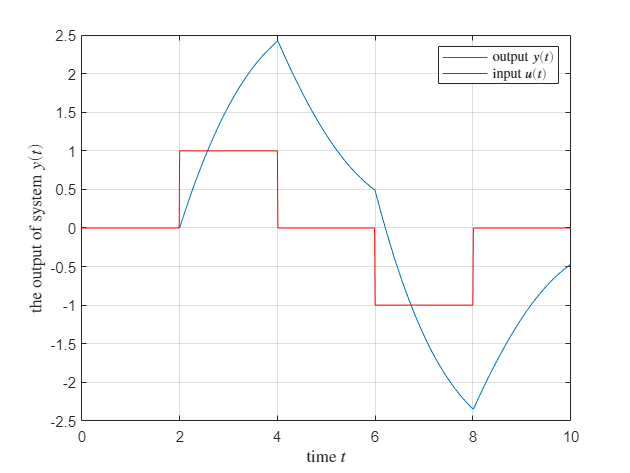

clear;
close all;
% the matrices A, B, C
A = [-1,1,0,0,0 ;
     0,-1,0,0,0;
     0,0,-2,0,0;
     0,0,0,-1,1;
     0,0,0,-1,-1];
B = transpose([0,1,1,0,1]);
C = [1,1,1,1,0];
% defining the time step
dt = 0.01;
Ts = dt;
t = 0:dt:10;
% defining the input
u = (t>=2 & t<=4) - (t>=6 & t<=8);
% defining the initial condition
x0 = [0,0,0,0,0];

X = zeros([length(A), length(t)]);
x0 = [0; 0; 0; 0; 0];
X(:, 1) = x0;
Y = zeros(size(t));
Y(1) = C * x0;
% solving through the difference equations
for i=2:length(t)
X(:, i) = X(:, i-1) + Ts * (A * X(:, i-1) + B * u(i-1));
Y(i) = C * X(:, i);
end

plot(t,Y);
hold on
plot(t,u,'r');
legend("output $y(t)$","input $u(t)$",'Interpreter', 'latex');
ylabel("the output of system $y(t)$",'Interpreter', 'latex');
xlabel("time $t$",'Interpreter', 'latex');
grid on

***Problem 9:***

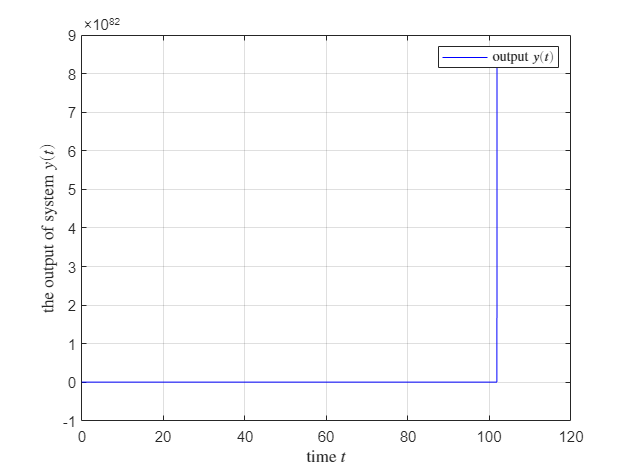

clear;
close all;

% defining the time step
dt = 0.01;
Ts = dt;
t = 0:dt:500;
% defining the input
uu = 25 + 5.*(t>=100 & t<=200) - 5.*(t>=300 & t<=400);
% defining the initial condition
x0 = [0.1; 0.1; 0.1];
% defining the states and the output
XX = zeros([length(x0), length(t)]);
YY = zeros(size(t));

% defining the initial condition of parameters
YY(1) = g(XX(:,1));
XX(:, 1) = x0;

% solving through the difference equations
for i=2:length(t)
XX(:, i) = XX(:, i-1) + Ts * f(XX(:, i-1), uu(i-1));
YY(i) = g(XX(:, i));
end

% plotting the results
plot(t,YY,'b');
%hold on
%plot(t,uu,'r');
legend("output $y(t)$","input $u(t)$",'Interpreter', 'latex');
ylabel("the output of system $y(t)$",'Interpreter', 'latex');
xlabel("time $t$",'Interpreter', 'latex');
grid on

function [A, B, C] = canonical_form_(sys, form)
    [numerator, denominator] = tfdata(sys, 'v');
      an = denominator;
      bn = numerator;
      n = length(an) - 1;
 % Controllable Canonical Form
    if form == 'C'
        A = zeros(n);
        B = zeros(n, 1);
        for i = 1:n-1
            A(i, i+1) = 1;
        end
        A(n, :) = -flip(an(2:end));        
        B(n) = 1;
        C = flip(bn(2:end));
 % Observable Canonical Form
    elseif form == 'O' 
        A = zeros(n);
        for i = 1:n-1
            A(i, i+1) = 1;
        end
        A(:, 1) = -flip(an(2:end));
        B = transpose(bn(2:end));
        C = [1, zeros(1, n-1)];
    else
        error('invalid input, the second argument must be either C or O');
    end
end
% ---------------------------------------------------------------------
function [dxdt] = f(x, u)
dxdt = [-x(1)*x(2) + sin(x(3)); 3*exp(-x(1)) - sqrt(x(3)); -x(3)^3 + u/(x(1) + x(2))];
end
% ---------------------------------------------------------------------
function [y] = g(x, u)
y = x(1)^2 - x(3);
end
%-------------
